This "live script" is meant to be run after cg_walker_sim, it analyzes the data given. It doesn't really have to be a live script I was just playing around with this new feature. 

tot = zeros(num_controllers,num_noise_vals);

for i = 1:num_controllers
   for j = 1:num_noise_vals
       for k = 1:num_trials
           if abs(max(eivals(:,i,j,k))) < 1
               tot(i,j,k) = 1;
           end
       end
   end
end

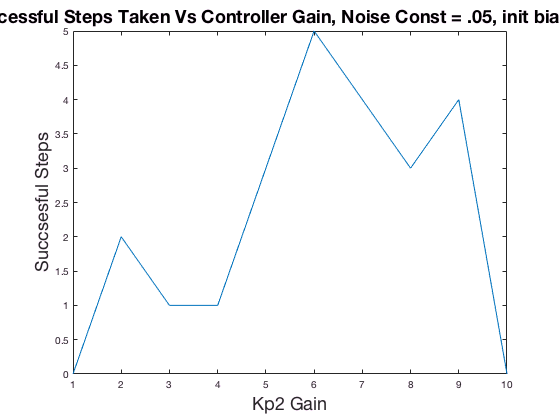

% Create figure
figure;

% Create axes
axes1 = axes;
hold(axes1,'on');

% Create plot
plot(tot(:,8));

% Create xlabel
xlabel('Kp2 Gain','FontSize',18);

% Create title
title('Successful Steps Taken Vs Controller Gain, Noise Const = .05, init bias = .05',...
    'FontSize',18);

% Create ylabel
ylabel('Succsesful Steps','FontSize',18);

% Uncomment the following line to preserve the Y-limits of the axes
% ylim(axes1,[0 10]);
box(axes1,'on');